## Pablo Vega Gallego, Adrian Cristian Crisan, Filip Gedung Dorm, VC, FIB. 

# Sessió 6

Començarem realitzant la part de binarització global.

Llegirem la imatge i la convertirem a escala de grisos i suavitzarem la imatge per tal de reduir el soroll de la captura.

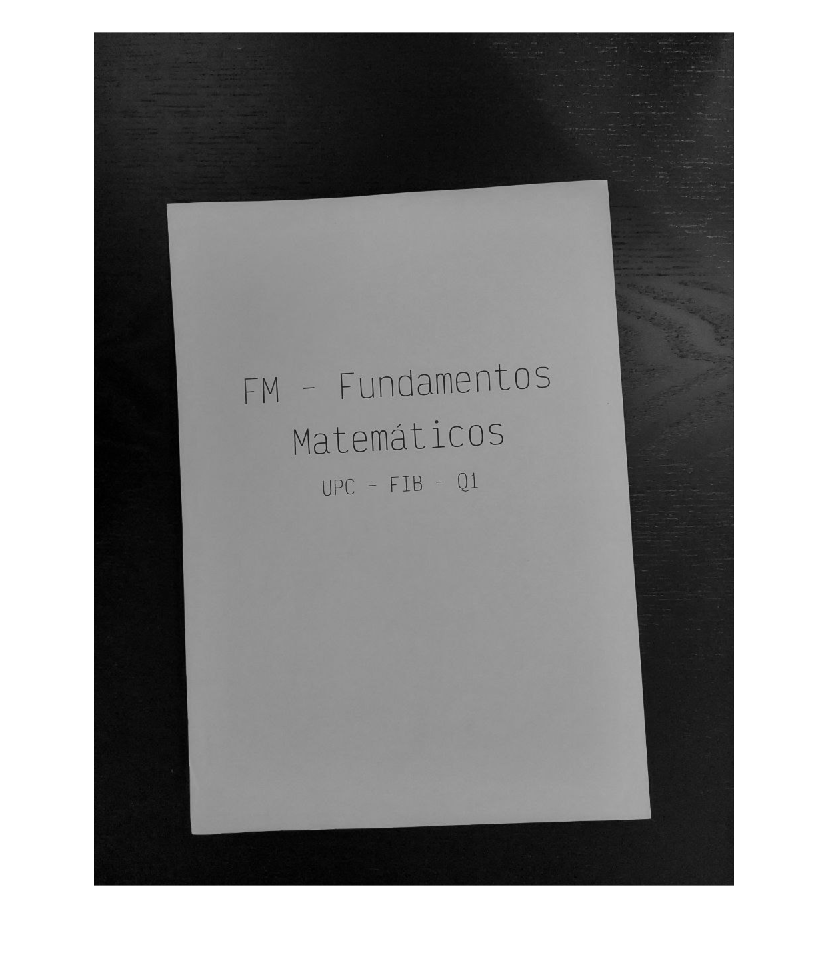

imagen_original = imread('foto1.jpeg');
imagen_grises = rgb2gray(imagen_original);

H = fspecial('gaussian');
imagen_grises = imfilter(imagen_grises, H);

imshow(imagen_grises);

Realitzarem l'histograma de la imatge per intentar separar la imatge en dos parts, més tard aplicarem otsu per separar aquestes dues parts.

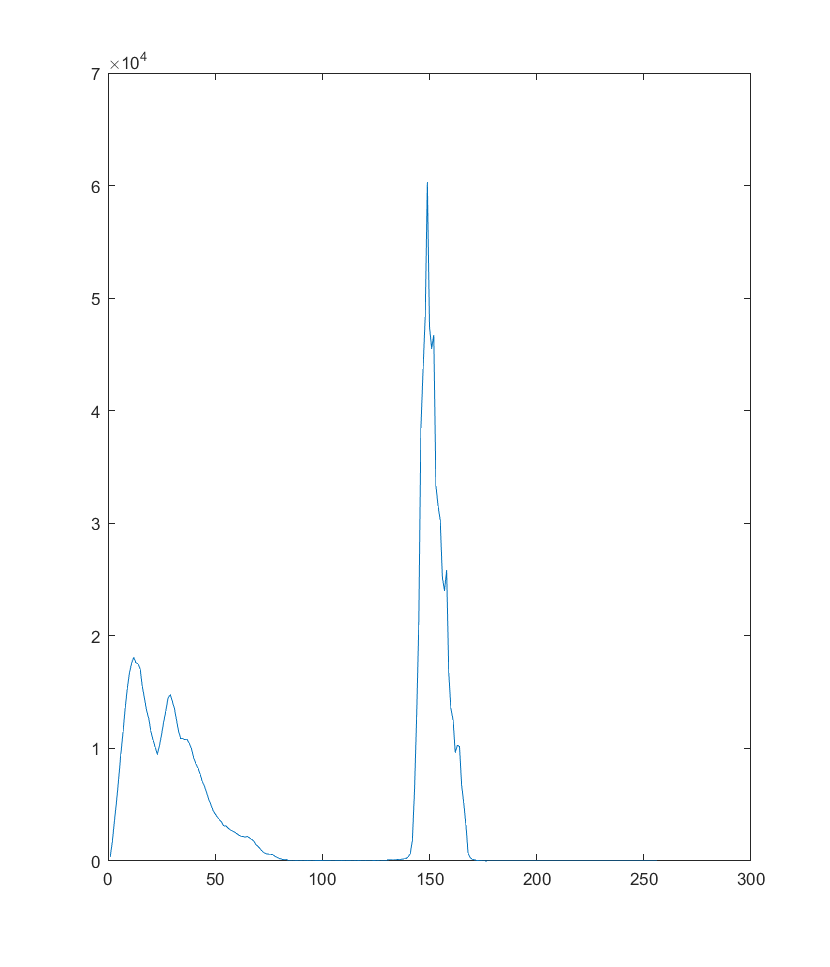

histograma_grises = imhist(imagen_grises);
plot(histograma_grises);

otsu = otsuthresh(histograma_grises) * 255

otsu = 88

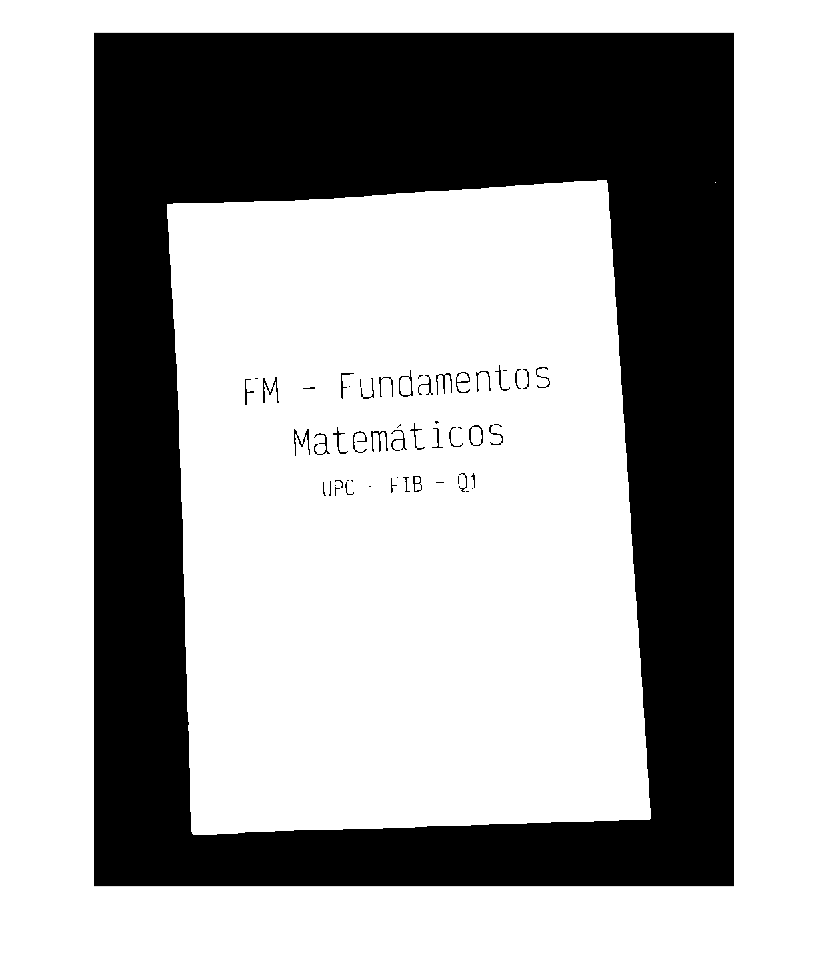

imagen_binarizada = imagen_grises > otsu + 20;
imshow(imagen_binarizada);

Traurem els marges de la imatge i rotem.

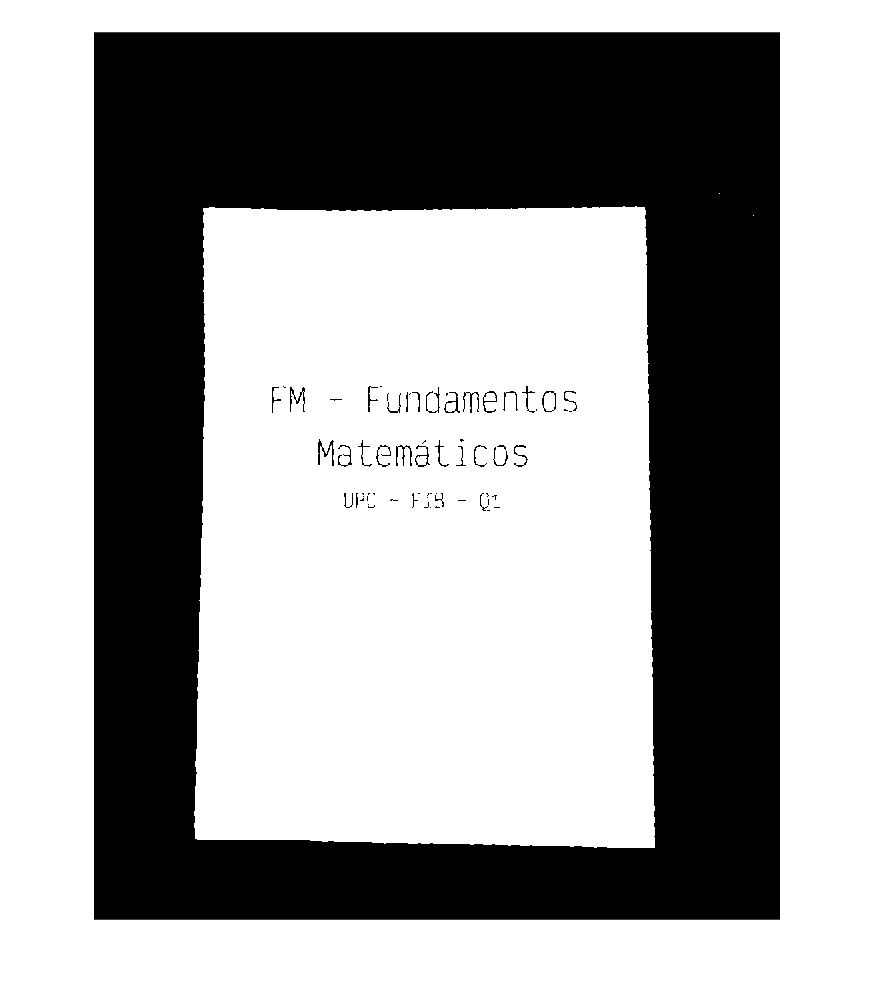

theta = rotacion(imagen_binarizada);
imagen_rotada = imrotate(imagen_binarizada, theta);
imshow(imagen_rotada);

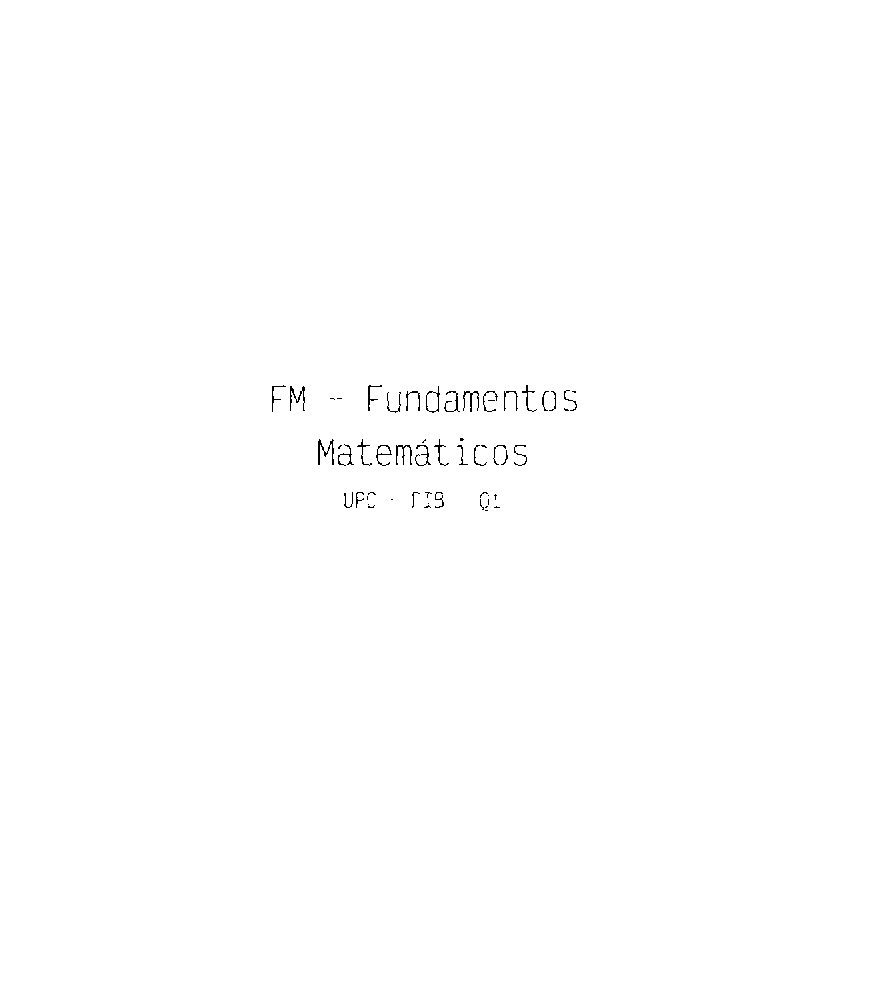

imagen_binarizada = imagen_rotada;

imagen_sin_bordes = quitarMargenes(imagen_binarizada);
imshow(imagen_sin_bordes);

Trobem les vores de la imatge i realitzem un crop d'aquesta per centrar la imatge a només el text.

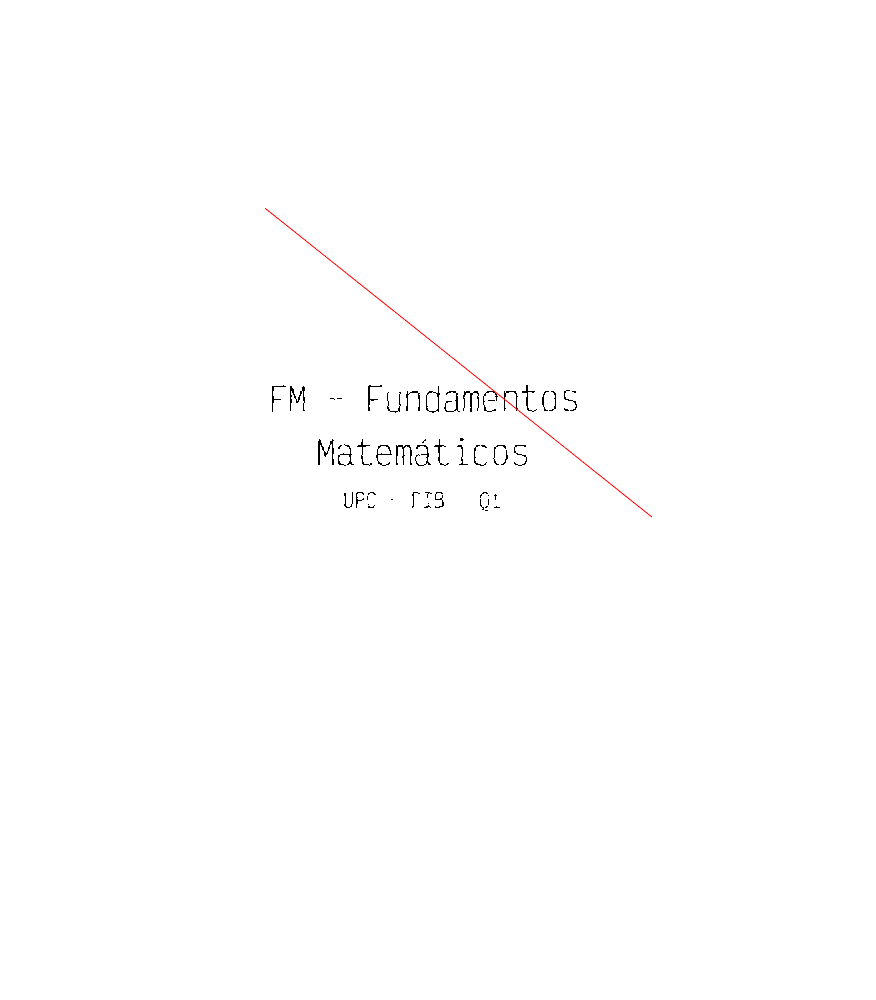

[ymin, xmin, ymax, xmax] = detectarExtremos(~imagen_sin_bordes);

imshow(imagen_sin_bordes)
hold on
plot([xmin, xmax], [ymin, ymax], 'r');
hold off

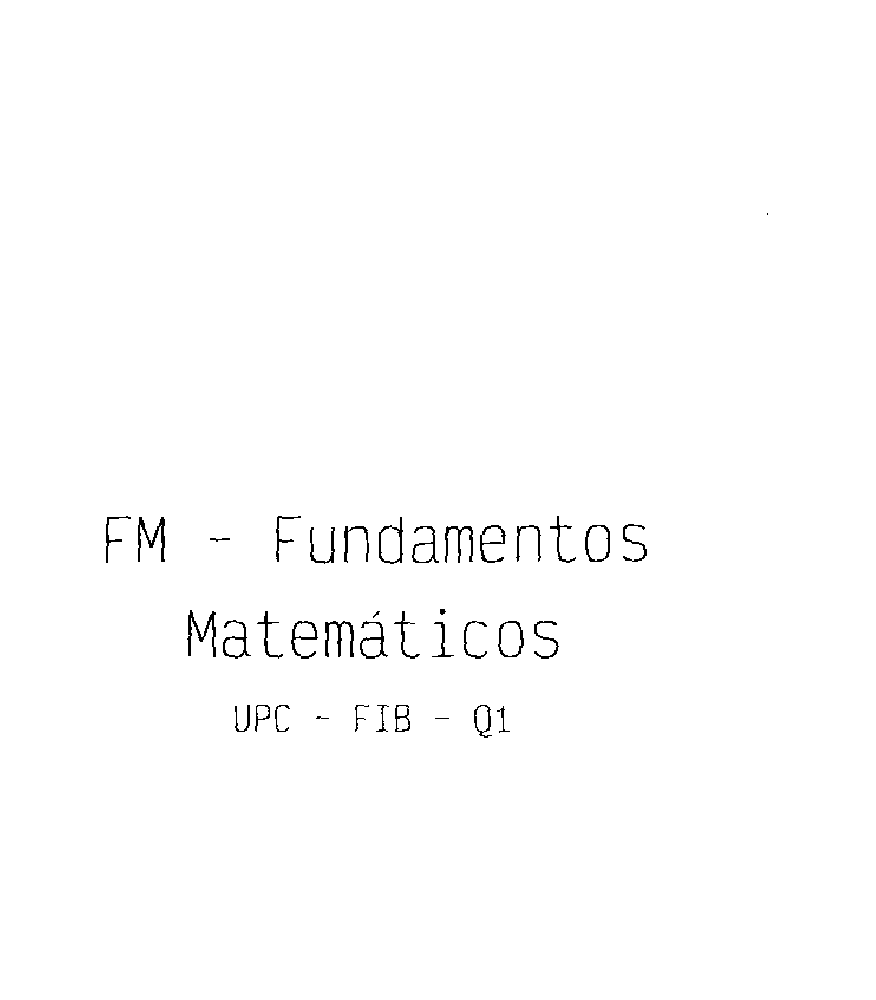

imagen_cortada = imcrop(imagen_sin_bordes, [xmin ymin xmax-xmin ymax-ymin]);
imshow(imagen_cortada)

Utilitzarem la separació d'ítems i encuadrarem els diferents. Trobem que apareixen 38 items, entre comes, punts, numeros, lletres i signes. Serien 37 però hi un puntet de soroll a la part dreta superior de la imatge.

labeledImage = bwconncomp(~imagen_cortada)

labeledImage = struct with fields:
    Connectivity: 8
       ImageSize: [464 581]
      NumObjects: 38
    PixelIdxList: {1×38 cell}


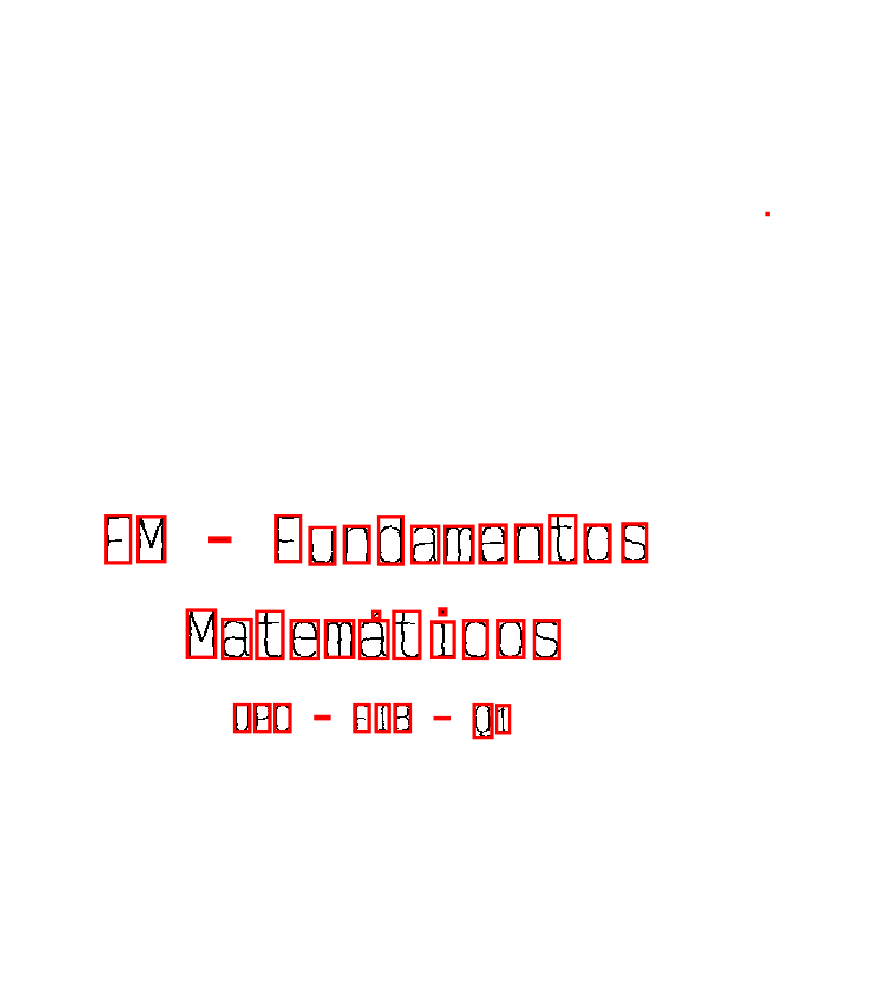

			measurements = regionprops(labeledImage,'BoundingBox');
for k = 1 : length(measurements)
thisBB = measurements(k).BoundingBox;
rectangle('Position', [thisBB(1),thisBB(2),thisBB(3),thisBB(4)],...
'EdgeColor','r','LineWidth',2 )
end

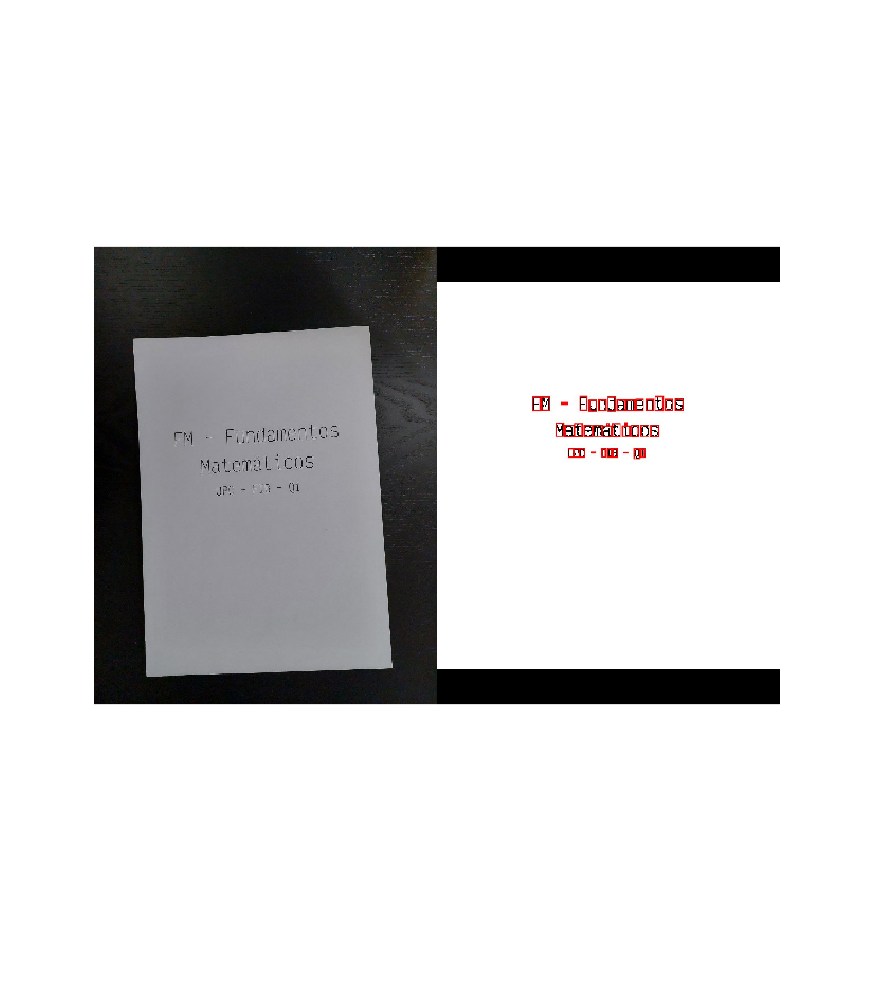

inicial = imread("foto1.jpeg");
final = imread("foto1_sol.jpg");
montage({inicial, final});

function theta = rotacion(imagen)
    [y, x] = find(imagen);
    
    nx = x - mean(x);
    ny = y - mean(y);
    
    nx = nx';
    ny = ny';
    
    c = cov(nx, ny);
    [evectors, evalues] = eig(c);
    
    [~, ind] = max(diag(evalues));
    
    theta = -pi/2-atan2(evectors(ind, 2), evectors(ind, 1));
end

function imagen = quitarMargenes(imagen_cortada)
    tamanoc = size(imagen_cortada);
    copia_imagen_cortada = imagen_cortada;
    resultado = imagen_cortada;
    
    i = 1;
    blanco = false;
    while ~blanco && i < tamanoc(1)
        j = 1;
        while ~blanco && j < tamanoc(2)
            blanco = imagen_cortada(i, j);
            imagen_cortada(i, j) = 1;
            j = j + 1;
        end
        blanco = false;
        i = i + 1;
    end
    
    resultado = resultado | imagen_cortada;
    
    imagen_cortada = copia_imagen_cortada;
    i = tamanoc(1);
    blanco = false;
    while ~blanco && i >= 1
        j = tamanoc(2);
        while ~blanco && j >= 1
            blanco = imagen_cortada(i, j);
            imagen_cortada(i, j) = 1;
            j = j - 1;
        end
        blanco = false;
        i = i - 1;
    end
    
    resultado = resultado | imagen_cortada;
    
    imagen_cortada = copia_imagen_cortada;
    
    j = 1;
    blanco = false;
    while ~blanco && j < tamanoc(2)
        i = 1;
        while ~blanco && i < tamanoc(1)
            blanco = imagen_cortada(i, j);
            imagen_cortada(i, j) = 1;
            i = i + 1;
        end
        blanco = false;
        j = j + 1;
    end
    
    resultado = resultado | imagen_cortada;
    
    imagen_cortada = copia_imagen_cortada;
    
    j = tamanoc(2);
    blanco = false;
    while ~blanco && j >= 1
        i = tamanoc(1);
        while ~blanco && i >= 1
            blanco = imagen_cortada(i, j);
            imagen_cortada(i, j) = 1;
            i = i - 1;
        end
        blanco = false;
        j = j - 1;
    end
    
    resultado = resultado | imagen_cortada;
    
    imagen = resultado;

end

function [xmin, ymin, xmax, ymax] = detectarExtremos(imagen)
    tamano = size(imagen);
    
    trobat = false;
    i = 1;
    while ~trobat && i <= tamano(1)
        acumulador = sum(imagen(i, :));
        if acumulador > 0
            trobat = true;
            xmin = i;
        end
        i = i + 1;
    end
    
    trobat = false;
    j = 1;
    while ~trobat && j <= tamano(2)
        acumulador = sum(transpose(imagen(:, j)));
        if acumulador > 0
            trobat = true;
            ymin = j;
        end
        j = j + 1;
    end
    
    trobat = false;
    i = tamano(1);
    while ~trobat && i >= 1
        acumulador = sum(imagen(i, :));
        if acumulador > 0
            trobat = true;
            xmax = i;
        end
        i = i - 1;
    end
    
    trobat = false;
    j = tamano(2);
    while ~trobat && j >= 1
        acumulador = sum(transpose(imagen(:, j)));
        if acumulador > 0
            trobat = true;
            ymax = j;
        end
        j = j - 1;
    end
    
    xmin = xmin - 10;
    ymin = ymin - 10;
    xmax = xmax + 10;
    ymax = ymax + 10;
end